Setup

clear;

% State space model parameters
lf = 1.3384; % front axle distance from CoG (m)
lr = 1.6456; % rear axle distance from CoG (m)
m = 2164; % Kg
I = 4373; % Kg * m^2
cf = 1.0745 * 10^5; % Frong cornering stiffness
cr = 1.9032 * 10^5; % Rear cornering stiffness

xdot_fn = bicycle_dyn_bodyalign_factory(m, I, lf, lr, cf, cr);
% xdot_fn = bicycle_kin_factory(lf, lr);

x0 = [
    0;
    0;
    0; % X(m), % lateral velocity
    0; % Y(m), % heading
    0; % Heading(rad) % yaw rate
]; 

% Input model parameters
sin_ampl = deg2rad(30); % rad
sin_freq = 0.5; % Hz
steer_fn = sinsteer_factory(sin_freq, sin_ampl);

velocity = 5;
vel_fn = constant_input_factory(velocity);

input_fn = input_fn_composer({steer_fn, vel_fn});

% Simulation parameters
t0 = 0; % s
ctrl_freq = 30; % Hz
t_max = 10; % s

Simulate system:

[xs, ts] = discrete_ctrl_sim(x0, t0, t_max, ctrl_freq, xdot_fn, input_fn);

Plot w.r.t. time

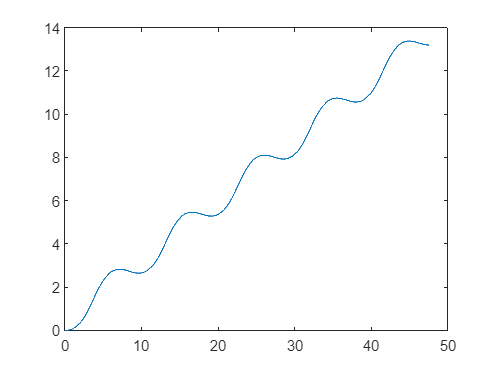

plot(xs(1,:), xs(2,:));

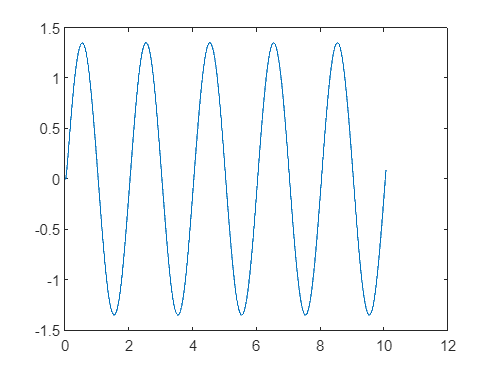

plot(ts, xs(3,:));

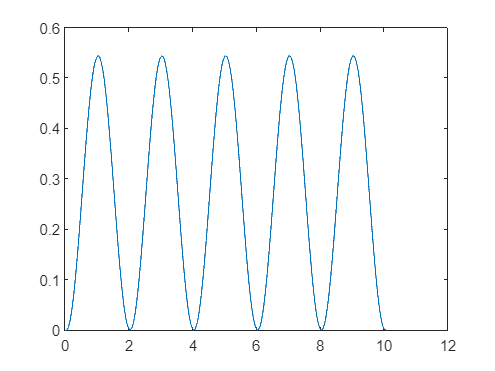

plot(ts, xs(4,:));

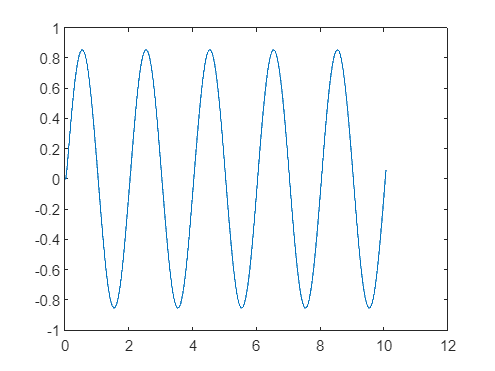

plot(ts, xs(5,:));